fprintf('please Select an image');

please Select an image

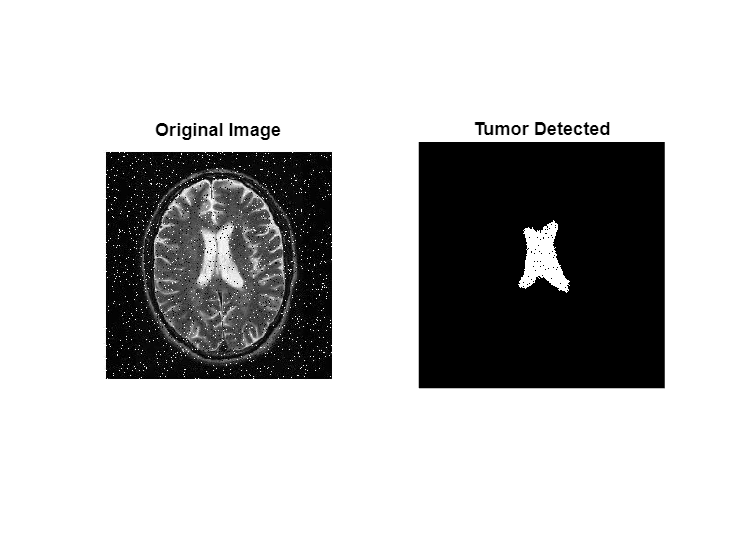

y=uigetfile('*.*');
i=imread(y);
image=rgb2gray(i);
subplot(1,2,1);
imshow(image);title("Original Image");


% Set the seed point and threshold value
seed_point = [250, 250];
threshold = 110;

% Call the region growing function
segmented_image = region_growing(image, seed_point, threshold);

% Display the segmented image
subplot(1,2,2);
imshow(segmented_image);title('Tumor Detected')